SPO_st.name='SPO';
SPO_st.lat=-89.98;
SPO_st.lon=-24.8;
SPO_st.alt=2410;
SPO_st.env='P';
SPO_st.footp='P';


SPO_rd2=read_betsy('spo_1979_2018',SPO_st.name);

SPO_rd=read_betsy('spo_1979_2018_longformat',SPO_st.name);

datevec(SPO_rd.Time(1))

ans =         1979           1           2           0           0           0

datevec(SPO_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(SPO_rd.U_S,[5 50 95])

ans =      0     0     0

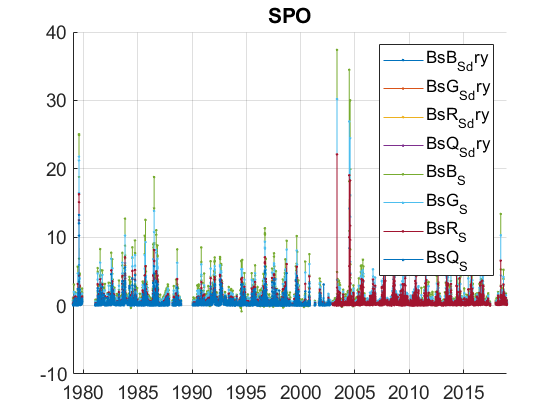

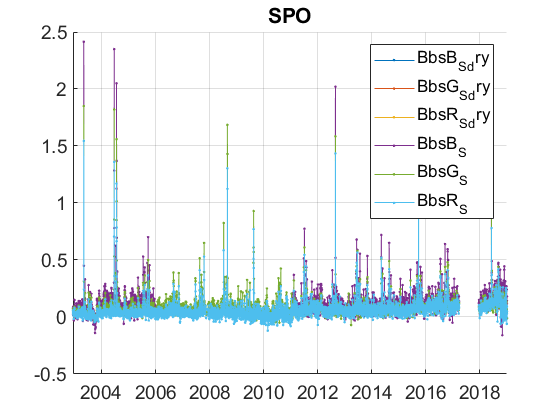

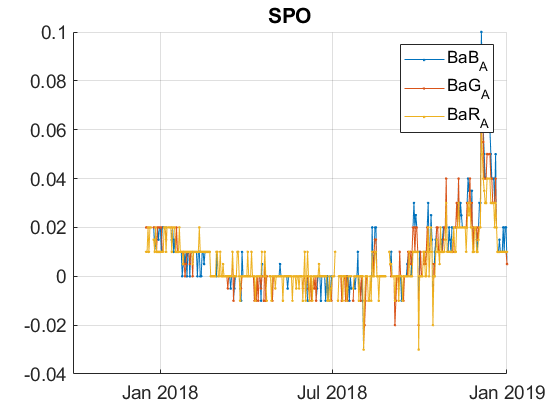

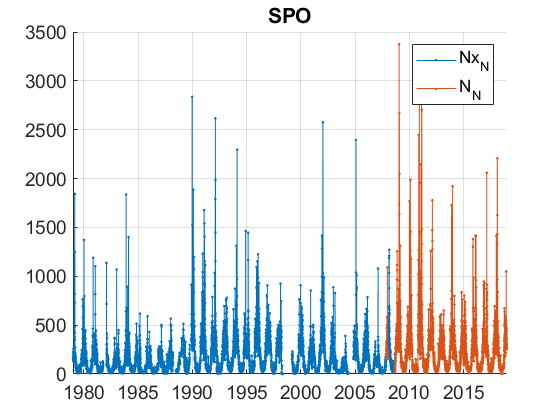

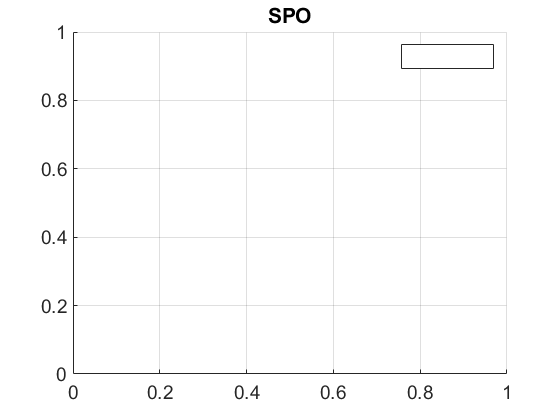

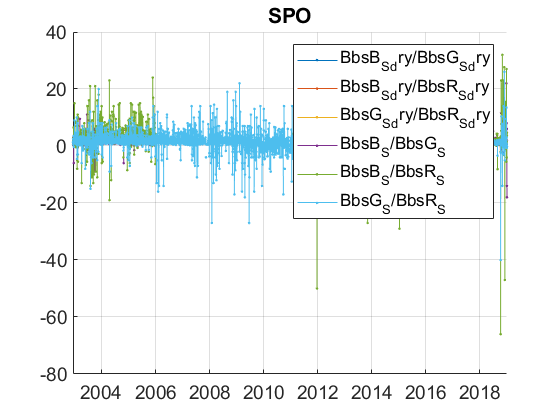

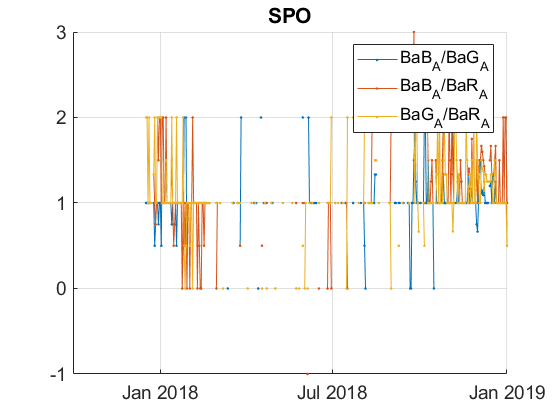

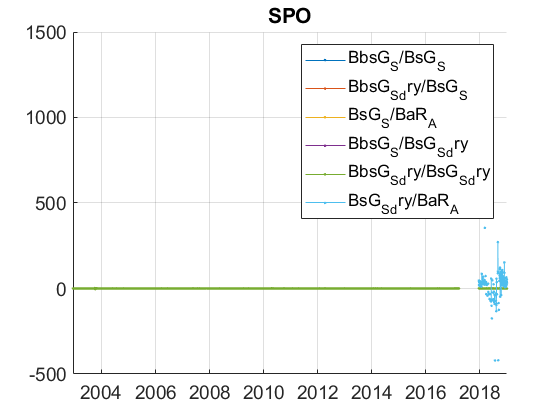

plotFigControl(SPO_rd, SPO_st.name);

% 1 size cut, ok
% sc: ok, max in SPOmer, with negatives
    


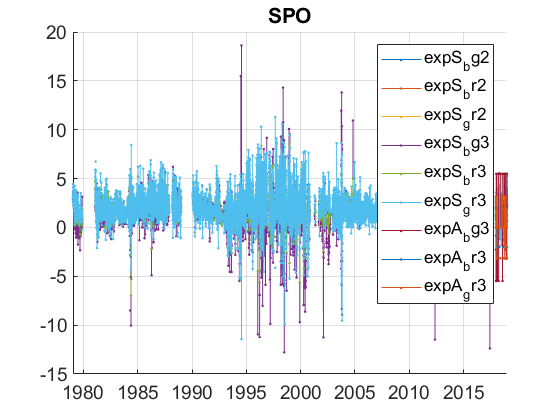

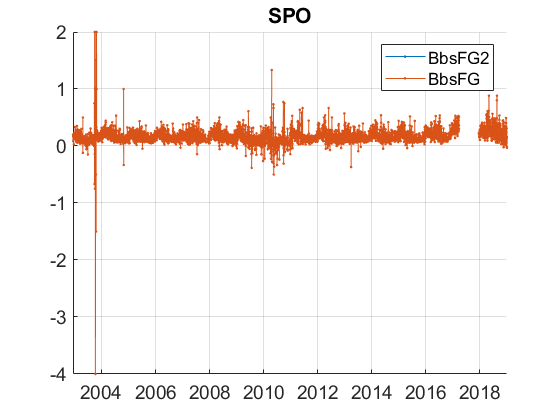

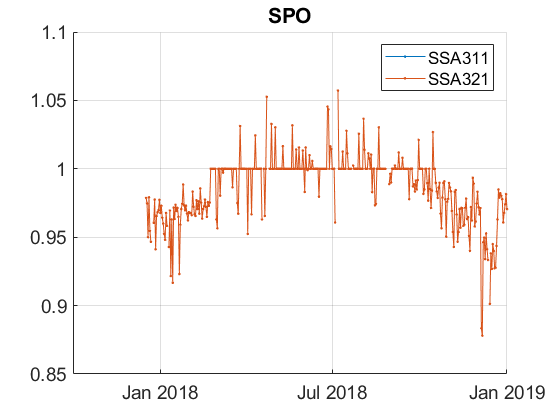

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
SPO_cal=compute_exp_SSA(SPO_rd,lambdaSC, lambdaAE);
plotFigControl_cal(SPO_cal, SPO_st.name);

%Questions:
%problems:

%SC: why nothing in blue from December 2005 to February 2011 ?
% no data from mid-June to mid December 2017: real hole or databank problem ?
%sc: why are the minima much lower from 1993 to2004 ?
%there is a large difference in maxima between 1986 and 1987, Is there any reason?
% there is a strange behavior in winter 1991-1992. Is there any reason to exclude these data?
% there is a change mostly visible in the backscatter in 2011 with higher values. This is also visible in the backscatter fraction. Do you have an explanation?
%the data from October 2018 to December 2018 are much lower than before. What is the reason?
% the BbsG/BbsR also has a change in 2011 with lower variability thereafter. just the same with the exponent. Any reason ?
% should we invalidate the large backscatter fraction extrema in September-October 2003 ?

%in 2013 we took only 2003-2010! Do we also restrict ourselves to data after 2003 = 

SPO_tr=SPO_rd;
SPO_tr.y=year(SPO_tr.Time);
% begin at the beginning of a year: scat: february 1979, hole then 1980
% untilfeb 1981.
%begin bacscat: 2003
%end 2018
P=timerange('1979-01-01','2019-01-01');
SPO_tr=SPO_tr(P,:);
%by now, only exp with gr available.

% U < 5%: no trend in U and in dry
%don't use abs: too short
names=fieldnames(SPO_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"U";"Ba"]) | endsWith(names,'_dry') | contains(names,'Q');
N=names(c);
for i=1:length(N)
    SPO_tr.(N{i})=[];
end

%backscat since 2003
names=fieldnames(SPO_tr);
P1=timerange('1979-01-01','2003-01-01');
c= startsWith(names,'Bbs');
N=names(c);
for i=1:length(N)
    SPO_tr.(N{i})(P1)=NaN;
end

%strange in 1991-1992: removre scat 4 oct 1991-24 march 1992
P2=timerange('1991-10-04','1992-03-24');
c= startsWith(names,'Bs');
N=names(c);
for i=1:length(N)
    SPO_tr.(N{i})(P2)=NaN;
end

%strange BbsF : invalidate all neph 23 sept 2003 to 28 oct 2003
P3=timerange('1993-09-23','1993-10-28');
c= startsWith(names,'B');
N=names(c);
for i=1:length(N)
    SPO_tr.(N{i})(P3)=NaN;
end

SPO_cal2=compute_exp_SSA(SPO_tr,lambdaSC, lambdaAE);
SPO_tr=outerjoin(SPO_tr, SPO_cal2);

%compute trend on G and expS_gr
SPO_tr.BsB_S11=[];

Cannot delete 'BsB_S' from the table because it does not exist. Assigning the literal value [] to a variable in a table deletes the variable. To create a new variable in the table with the value [], use T.BsB_S = zeros(0) or assign first to a temporary workspace variable.

SPO_tr.BsR_S11=[];
SPO_tr.BbsB_S11=[];
SPO_tr.BbsR_S11=[];
SPO_tr.expS_bg3=[];
SPO_tr.expS_br3=[];

SPO_result=all_trend_STN(SPO_tr,SPO_st);
plot_10y_in_two(SPO_result,SPO_st);

SPO_result_D=SPO_result;